**Data**

x = [10 20 30 40 50 60 70 80]';

y = [25 70 380 550 610 1220 830 1450]';

**Plot data**

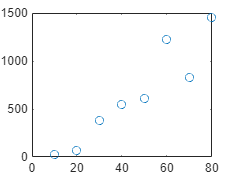


plot(x,y,'o')

**Create Z matrix**


z = [ones(8,1) x x.^2]

z =            1          10         100
           1          20         400
           1          30         900
           1          40        1600
           1          50        2500
           1          60        3600
           1          70        4900
           1          80        6400


**Solve for unknown parameters  a  **

a = (z'*z) \ (z'*y)

a =  -178.4821
   16.1220
    0.0372


**Plot data and the best fitted curve**

xx = 3 : 0.5 : 12

xx =     3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000



yy = a(1) + a(2).*xx + a(3).*xx.*xx

yy =  -129.7813 -121.5993 -113.3988 -105.1797  -96.9420  -88.6856  -80.4107  -72.1172  -63.8051  -55.4743  -47.1250  -38.7571  -30.3705  -21.9654  -13.5417   -5.0993    3.3616   11.8411   20.3393


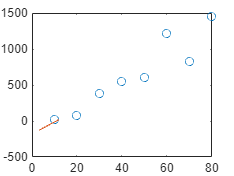


plot(x,y,'o',xx,yy,'-')

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y-z*a).^2)

Sr = 2.1379e+05

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)

St = 1.8083e+06

**Compute  r2  (the coefficient of determination)**

r2 = 1 - Sr/St

r2 = 0.8818

**Compute  syx  (the standard error of the estimate)  **


syx = sqrt(Sr/(length(x)-length(a)))

syx = 206.7815

**Predict the value of y for the given x**

xtest = 6;
predict_y = a(1) + a(2).*xtest + a(3).*xtest.*xtest

predict_y = -80.4107